% clear;
data = load('resultadosCSV_66khz.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27
n_max_start = 335
T           = 5e-9;


T_buscado = 1/(2*66e3)

T_buscado =      7.575757575757576e-06


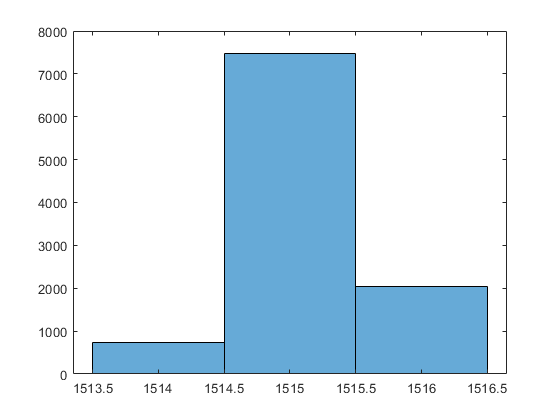

t_fino = (start-n_min_start)*tau_start - (stop-n_min_stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse)

indices_1514 = find(coarse==1514);
indices_1515 = find(coarse==1515);
indices_1516 = find(coarse==1516);

%%Coarse 1514
(1514*T - T_buscado)/T %%entonces hay que sumarle un clock!!

ans =   -1.151515151515043


fino_1514 = t_fino(indices_1514);
cant1514 = length(fino_1514)

cant1514 =    740


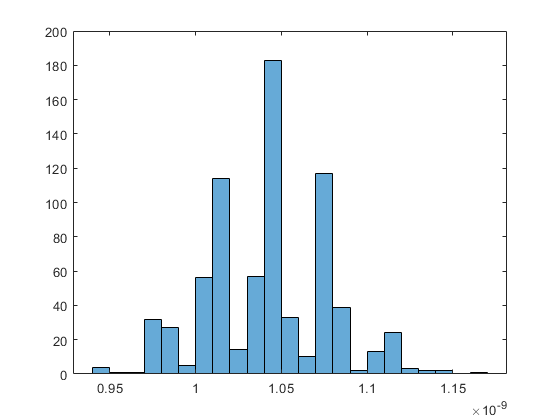

histogram(fino_1514);


%%Coarse 1515
(1515*T - T_buscado)/T

ans =   -0.151515151515053


fino_1515 = t_fino(indices_1515);
cant1515 = length(fino_1515)

cant1515 =         7468


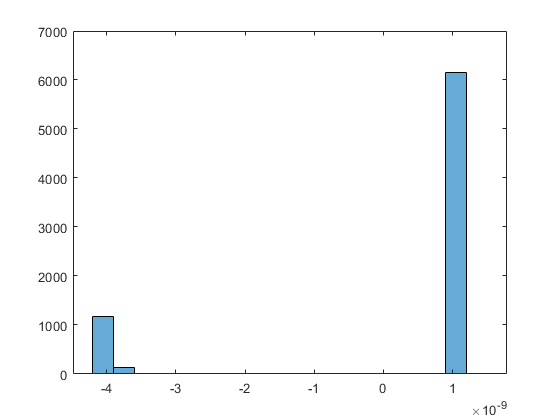

histogram(fino_1515)

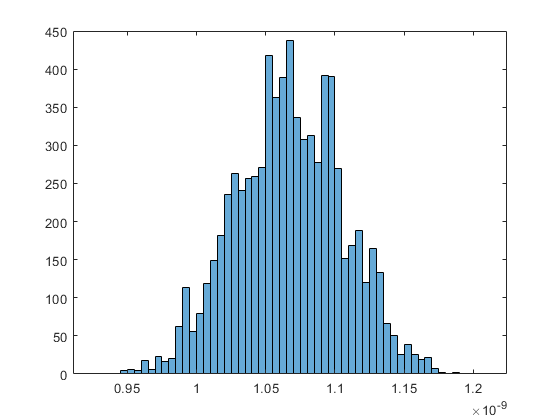

fino_1515_buenos = fino_1515(fino_1515>0);
fino_1515_malos = fino_1515(fino_1515<0);
histogram([fino_1515_buenos; fino_1515_malos+T])


%%Coarse 1516
(1516*T - T_buscado)/T %%se pasó un clock

ans =    0.848484848484938


fino_1516 = t_fino(indices_1516);
cant1516 = length(fino_1516)

cant1516 =         2032


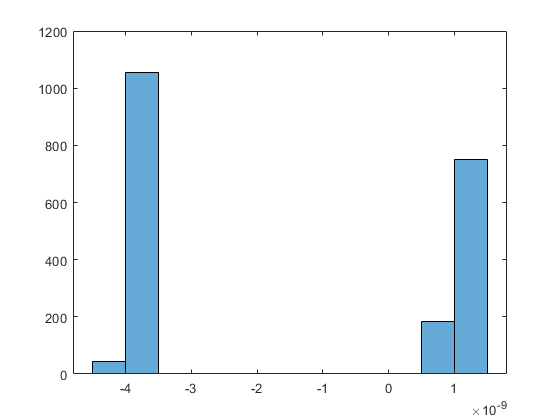

histogram(fino_1516);

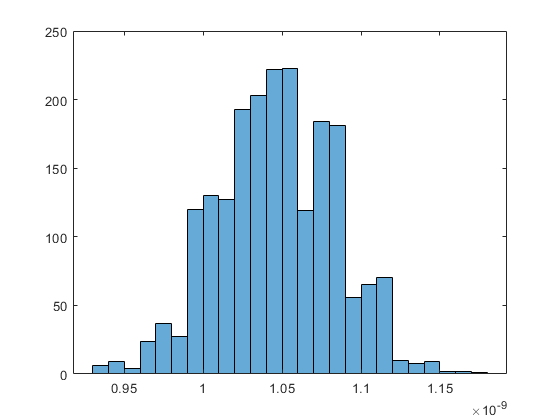

fino_1516_buenos = fino_1516(fino_1516<0);
fino_1516_malos  = fino_1516(fino_1516>0);
histogram([fino_1516_buenos+T; fino_1516_malos])

clf;
y = [fino_1514; fino_1515_buenos; fino_1515_malos+T; fino_1516_buenos+T; fino_1516_malos];
presicion = std(y)

presicion =      3.962168339320981e-11


media     = mean(y)

media =      1.061293202148427e-09


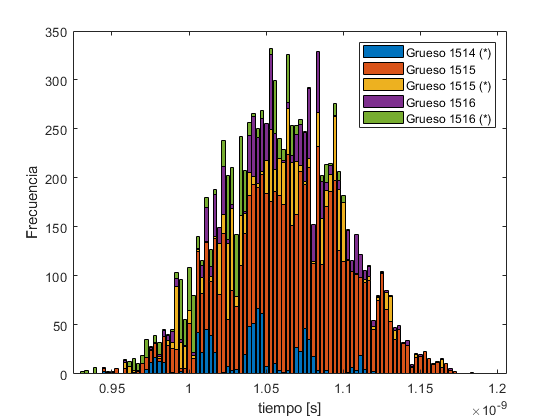

coarse_correcto = 1515;
N = 100;
% Clear figure
clf;

% Data vectors
data = {fino_1514, fino_1515_buenos, fino_1515_malos+T, fino_1516_buenos+T, fino_1516_malos};

% Number of bins
N = 100;

% Determine the range for the common bin edges
all_data = y;
min_val = min(all_data);
max_val = max(all_data);

% Create common bin edges
commonEdges = linspace(min_val, max_val, N+1);

% Preallocate array for counts
countsMatrix = zeros(N, length(data));

% Calculate counts using common edges
for i = 1:length(data)
    countsMatrix(:, i) = histcounts(data{i}, commonEdges);
end
% Create stacked bar plot
bar(commonEdges(1:end-1), countsMatrix, 'stacked');
xlabel('tiempo [s]');
ylabel('Frecuencia');
legend({'Grueso 1514 (*)', 'Grueso 1515', 'Grueso 1515 (*)', 'Grueso 1516', 'Grueso 1516 (*)'});
exportgraphics(gcf,'histograma_66k.eps');


format long
T_buscado

T_buscado =      7.575757575757576e-06


Tiempo_final = 1515*T + media

Tiempo_final =      7.576061293202149e-06


error = Tiempo_final - T_buscado

error =      3.037174445733485e-10
